# Reconstruction of gene regulatory networks using PANDA

**Author:**

Marouen Ben Guebila

## Gene regulatory networks

Living organisms respond to perturbation through varying their transcriptional state. The development of RNA sequencing techniques allows to measure the transcriptome in a fast manner. It is equally important to determine the transcription factor (TF) regulators that induce the transcriptional control.

PANDA [1] (Passing Attributes Between Networks for Data Assimilation) allows to build a gene regulatory network linking the TFs to their putative genes in a bipartite graph. The algorithm starts from an intial gene regulatory network built through the scanning the genome for TF binding site, hence called the motif prior. Using the motif prior as a gene regulatory network can yield a high number of false positive, as other epigenetic factors play a role in TF-gene interaction.

Next, PANDA uses PPI interaction networks between TFs to infer complexes that are likely to collectively regulate a given gene [1]. Finally, PANDA uses gene expression as a third prior to infer co-regulated genes through the co-expression networks. If two genes are correlated, they are likely to have the same regulators. In the end, PANDA refines the initial prior motif network through iteratively updating with coexpression networks and PPI networks.

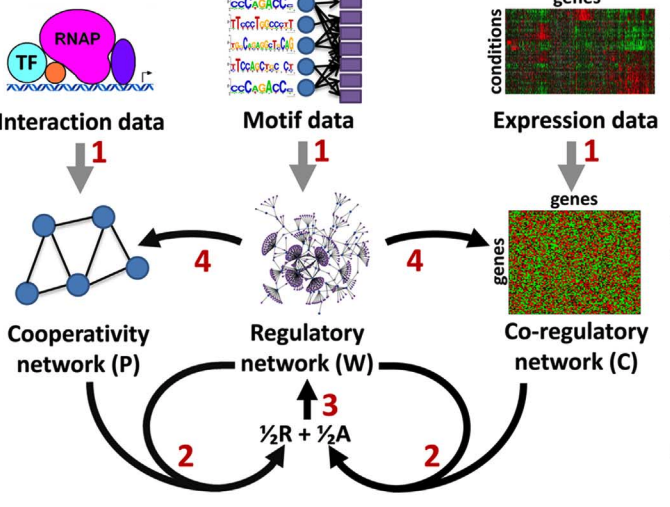

## Using PANDA to infer gene regulatory networks

For this tutorial, we will reconstruct a gene regulatory network using toy data and the PANDA function implemented in the netZooM package of network biology methods.

### Install netZooM

You can git clone [https://github.com/netZoo/netZooM.git](https://github.com/netZoo/netZooM.git) to your local directory. Then add it in your MATLAB path.

addpath(genpath('path/to/netZooM'))

### Set the parameters

First, we start by setting the path to the 1) motif prior network, 2) the gene expression data, and 3) the ppi network data. The motif prior network is typically a TF-by-gene binary matrix where 1 indicates the presence of sequence (motif) of a TF in the gene regulatory region and 0 otherwise. Gene expression data is typically a gene-by-sample matrix containing expression data. PPI network is a TF-by-TF binary matrix, where 1 indicates a physical interaction between two TFs and 0 otherwise. If two TFs are likely to binding, they are likely ot form regulatory complexes for the same genes.

% Set Program Parameters
exp_file   = 'tests/test_data/expression.txt';
motif_file = 'tests/test_data/motif.txt';
ppi_file   = 'tests/test_data/ppi.txt';
panda_out  = '';  % optional, leave empty if file output is not required
lib_path   = '../netZooM';  % path to the folder of PANDA source code

For now, we will set the saving path to empty because we do not want to save the results.

save_temp  = '';  % optional, leave empty if temp data files will not be needed afterward

Set the learning rate alpha. Typically a learning rate of 0.1 is recommended for most applications. You can save the final network in a matrix format or a pairs format.

alpha      = 0.1;
save_pairs = 0; %saving in .pairs format

### Exploring the data

- First, let's determine the number of samples and the number of genes in our gene expression data.

expressionData = readtable('expression.txt');
size(expressionData)

ans =         1000          51


There are 1000 genes and 51 samples in our toy data.

- Second, let's see how many TFs and genes does our motif prior cover.

[TF, gene, weight] = textread(motif_file, '%s%s%f');
TFNames = unique(TF)

There are 661 TFs covered in our prior motif network.

- Finally, let's check our last prior, the PPI TF-TF network.

[TF1, TF2, weight] = textread(ppi_file, '%s%s%f')

The PPI network covers  86609 physical binding interaction between TFs.

### Prior1: Build coexpression network

First, we read the expression data.

disp('Reading in expression data!');
fid = fopen(exp_file, 'r');
headings = fgetl(fid);
n = length(regexp(headings, '\t'));
frewind(fid);
Exp = textscan(fid, ['%s', repmat('%f', 1, n)], 'delimiter', '\t'); 
fclose(fid);
GeneNames = Exp{1};
Exp = cat(2, Exp{2:end});
[NumGenes, NumConditions] = size(Exp);
fprintf('%d genes and %d conditions!\n', NumGenes, NumConditions);
Exp = Exp';  % transpose expression matrix from gene-by-sample to sample-by-gene

Then, we compute a coexpression network.

disp('Computing coexpression network:');
GeneCoReg = Coexpression(Exp);

### Prior2: Build TF binding motif network 

Then, we read the TF-TF PPI network.

disp('Reading in motif data!');
[TF, gene, weight] = textread(motif_file, '%s%s%f');
TFNames = unique(TF);
NumTFs = length(TFNames);
[~,i] = ismember(TF, TFNames);
[~,j] = ismember(gene, GeneNames);
RegNet = zeros(NumTFs, NumGenes);
RegNet(sub2ind([NumTFs, NumGenes], i, j)) = weight;
fprintf('%d TFs and %d edges!\n', NumTFs, length(weight));

### Prior3: Build TF-TF PPI network

Next, we build TF-TF PPI network that allows us to find indirect regulatory agents. In fact, some TF do not bind directly to the DNA but rather to other TFs.

disp('Reading in ppi data!');
TFCoop = eye(NumTFs);
if(~isempty(ppi_file))
    [TF1, TF2, weight] = textread(ppi_file, '%s%s%f');
    [~,i] = ismember(TF1, TFNames);
    [~,j] = ismember(TF2, TFNames);
    TFCoop(sub2ind([NumTFs, NumTFs], i, j)) = weight;
    TFCoop(sub2ind([NumTFs, NumTFs], j, i)) = weight;
    fprintf('%d PPIs!\n', length(weight));
end

### Normalize the networks

To avoid biases due to the sequencing plateforma and the different scales of the measurments, we need to normalize the three prior networks.

disp('Normalizing Networks:');
RegNet = NormalizeNetwork(RegNet);
GeneCoReg = NormalizeNetwork(GeneCoReg);
TFCoop = NormalizeNetwork(TFCoop);

### Calling PANDA

Fianlly, we call the PANDA function to perform the iterative optimisation procedure.

disp('Running PANDA algorithm:');
AgNet = PANDA(RegNet, GeneCoReg, TFCoop, alpha);

The final result network AgNet is a complete bipartite network.

### Running PANDA using the wrapper function

We can either process each prior separatly or we can call panda_run that does all the previous steps through the following command:

AgNet = panda_run(lib_path,exp_file, motif_file, ppi_file, panda_out, save_temp, alpha, save_pairs);

The final network AgNet is a bipartite network represented in a TF-by-gene matrix with continuous values representing the likelihood of binding for each TF-gene pair.

### Basic analysis

Using this refined gene regulatory network, we can perform a number of analyses. Our toy model has 661 TFs and 1000 genes. We can compute the gene targeting for each gene, i.e., the likelihood that a given gene is regulated by transcription factors. Simply, we can compute the in-degree for each gene.

sum(AgNet,2)

Gene targeting as opposed to gene expression, is a useful measure to assess the summary regulatory interactions for a given gene.

We can also compute the TF regulatory potentiel, ie., the likelihood of a given TF to regulate a set of genes. Simply, we compute the out-degree of each TF in our network

sum(AgNet,1)

### Further analyses

The final network can be reduced to the most important edge weights to retain the most important interactions. Also, you can perform communtiy detection on the final graph to find groups of regulators that act together. Morevoer, you can generate single sample networks for each sample in the input gene expression data. Check the netZoo for more details on these methods.

### References

[1] Glass, Kimberly, et al. "Passing messages between biological networks to refine predicted interactions." *PloS one* 8.5 (2013): e64832.